clear all
clc
syms xR(t) xD(t) yR(t) yD(t) theta(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t) TR(t) TD(t) mR L mD g r

animate_it = 1;     % set to 1 to plot the animation
save_it = 0;        % set to 1 to save the animation



IGR=1/12*mR*L^2; IGD=1/2*mD*r^2;

rGR=[xR(t);yR(t)];
rGD=[xD(t);yD(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];


% this is the disk acceleration required to keep the bar horizontal if
% initial theta = pi/2
disk_acceleration = -(mR*g*L/2 + mD*g*L)/IGD;


% Force 1 acts on the rod at the pivot
% Force 2 acts on the rod at the connection to the disk
% Froce 3 acts on the disk at the connection to the rod

%F=ma for rod
eq1=mR*diff(rGR,t,t)==F1+F2-mR*g*[0;1];
MF1GR=cross(-[rGR;0],[F1;0]);
MF2GR=cross([rGR;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IGR*diff(theta(t),t,t)==MF1GR(3)+MF2GR(3)+TR(t);

%F=ma for the disk
eq3=mD*diff(rGD,t,t)==F3-mD*g*[0;1];
%IG theta''=M for the disk.
eq4=IGD*(diff(theta(t),t,t) + disk_acceleration) == TD(t);

%Keep rod anchored at origin. 
eq5=rGR+L/2*[-sin(theta(t));cos(theta(t))]==[0;0];
%Keep disk pinned to rod
eq6=rGD+L*[-sin(theta(t));cos(theta(t))]==[0;0];
%F2 and F3 must be related. 
eq7=F2==-F3;
%the torques from the motor accelerating the disk must be related
eq8=TR(t)==-TD(t);

DES=[eq1;eq2;eq3;eq4;eq7;eq8];
disp_const=[eq5;eq6];
vel_const = [];


%Generate the governing equations.  Notice that we can see right off that
%if sin(theta(t))==1 then diff(theta)==0!
[DEs, PPs]=generateGoveringDEs(DES,disp_const,vel_const,[theta,diff(theta)])

The unknown functions are:
F1x(force)
F2x(force)
F3x(force)
F1y(force)
F2y(force)
F3y(force)
TD(force)
TR(force)
theta
xD
xR
yD
yR

Expected Number of State Variables:2


$$DEs = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{6\,\left(2\,L\,g\,\mathrm{mD}+L\,g\,\mathrm{mR}-2\,L\,g\,\mathrm{mD}\,\sin\left(\theta \left(t\right)\right)-L\,g\,\mathrm{mR}\,\sin\left(\theta \left(t\right)\right)\right)}{L^{2}\,\mathrm{mR}+6\,\mathrm{mD}\,r^{2}+12\,L^{2}\,\mathrm{mD}\,\sigma_{1}+3\,L^{2}\,\mathrm{mR}\,\sigma_{1}+12\,L^{2}\,\mathrm{mD}\,\sigma_{2}+3\,L^{2}\,\mathrm{mR}\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\sin\left(\theta \left(t\right)\right)}^{2} \end{array}$$

simplify(rhs(DEs))

$$ans = -\frac{3\,L\,g\,\left(2\,\mathrm{mD}+\mathrm{mR}\right)\,\left(\sin\left(\theta \left(t\right)\right)-1\right)}{6\,L^{2}\,\mathrm{mD}+2\,L^{2}\,\mathrm{mR}+3\,\mathrm{mD}\,r^{2}}$$


parameterVals.mR=1; parameterVals.mD=2; parameterVals.L=3; parameterVals.r=0.5; parameterVals.g=9.81;% kg and m 
specificDEs=subs(DEs,parameterVals);
specificPPs=subs(PPs,paramterVals);


The unknown functions (just the base functions, not derivatives) are: theta(t)


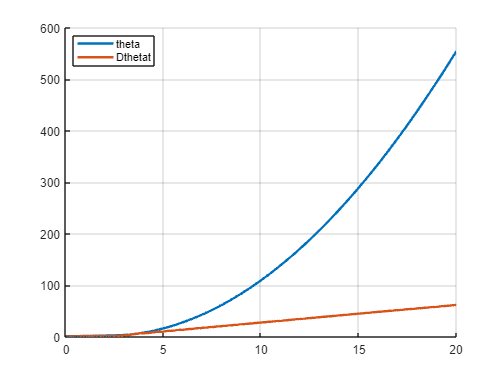


soln=timeStepODESystem(specificDEs,[0,20],[theta==pi/4,diff(theta)==0]);

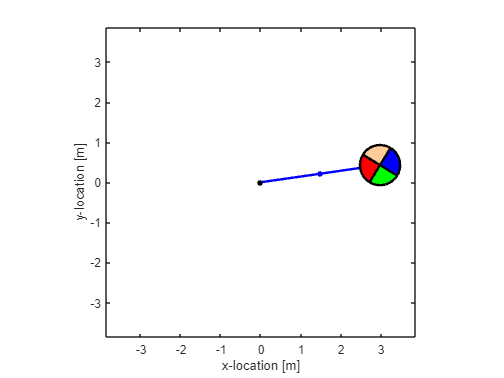

if animate_it == 1
    t_anim = linspace(min(soln.t),max(soln.t),201)';
    theta_anim = interp1(soln.t,soln.theta,t_anim);
    phi_anim = eval(subs(1/2*disk_acceleration*t_anim.^2,parameterVals));
    func_animate_levitating_disk(t_anim,theta_anim,phi_anim,parameterVals.L,parameterVals.r,save_it)
end

% omega_disk = disk_acceleration*soln.t;
% KineticEnergy=1/2*mR*(soln.DxRt.^2+soln.DyRt.^2)+1/2*mD*(soln.DxDt.^2+soln.DyDt.^2)...
%     +1/2*IGR*soln.Dthetat.^2+1/2*IGD*(soln.Dthetat + omega_disk).^2;
% PotentialEnergy=mR*soln.yR*g+mD*soln.yD*g;
% PotentialEnergy = PotentialEnergy - PotentialEnergy(1);
% figure
% clf
% hold on
% plot(soln.t,KineticEnergy,'LineWidth',2)
% plot(soln.t,PotentialEnergy,'LineWidth',2)
% plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
% xlabel('time'); ylabel('Total Energy')
% legend('Kinetic','Potential','Total')

function [] = func_animate_levitating_disk(t,theta,phi,L,r,save_it)

skip_frame = 1;

if save_it == 1
    %--------------------------------------------------------------------------
    % animate the results
    saveDirName = uigetdir('', ['Specify the directory where the ', ...
        'animations will be saved.']);

    %  Append a slash to the directory name ('/' for Mac, '\' for Windows):
    if isempty(strfind(saveDirName, '/')) == 0
        saveDirName = [saveDirName, '/'];
    else
        saveDirName = [saveDirName, '\'];
    end

    animObj = VideoWriter([saveDirName, 'double_pendulum.avi']);
    open(animObj)
    skip_frame = 5;
end

% plot the angular displacements
figure(1)
clf
plot(0,0)
xlabel('x-location [m]')
ylabel('y-location [m]')
axis equal
axis([-1.1*(L+r) 1.1*(L+r) -1.1*(L+r) 1.1*(L+r)])

quadrant1 = [...
    0, r*cosd(0:90);...
    0, r*sind(0:90);...
    zeros(1,92)];
quadrant2 = [...
    0, r*cosd(90:180);...
    0, r*sind(90:180);...
    zeros(1,92)];
quadrant3 = [...
    0, r*cosd(180:270);...
    0, r*sind(180:270);...
    zeros(1,92)];
quadrant4 = [...
    0, r*cosd(270:360);...
    0, r*sind(270:360);...
    zeros(1,92)];

for k = 1:length(t)

    R_a_I = [sin(theta(k)) cos(theta(k)) 0;-cos(theta(k)) sin(theta(k)) 0;0 0 1];
    R_b_a = [cos(phi(k)) -sin(phi(k)) 0;sin(phi(k)) cos(phi(k)) 0;0 0 1];

    rAx(k,1) = 0;
    rAy(k,1) = 0;

    temp = R_a_I*[L/2;0;0];
    rGRx(k,1) = temp(1);
    rGRy(k,1) = temp(2);

    temp = R_a_I*[L;0;0];
    rGDx(k,1) = temp(1);
    rGDy(k,1) = temp(2);

    temp = [rGDx(k,1);rGDy(k,1);0] + R_a_I*R_b_a*quadrant1;
    q1x(k,:) = temp(1,:);
    q1y(k,:) = temp(2,:);

    temp = [rGDx(k,1);rGDy(k,1);0] + R_a_I*R_b_a*quadrant2;
    q2x(k,:) = temp(1,:);
    q2y(k,:) = temp(2,:);

    temp = [rGDx(k,1);rGDy(k,1);0] + R_a_I*R_b_a*quadrant3;
    q3x(k,:) = temp(1,:);
    q3y(k,:) = temp(2,:);

    temp = [rGDx(k,1);rGDy(k,1);0] + R_a_I*R_b_a*quadrant4;
    q4x(k,:) = temp(1,:);
    q4y(k,:) = temp(2,:);
end

%  Specify the quadrant colors:
c1 = [1, 0.8, 0.6];
c2 = [1, 0, 0];
c3 = [0, 1, 0];
c4 = [0, 0, 1];

%  Draw pendulums, joints, and CGs
rod = line('xdata', [rAx(1) rGDx(1)], 'ydata', [rAy(1) rGDy(1)],...
    'color','b','linewidth',2);
pointA = line('xdata', rAx(1), 'ydata', rAy(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 4);
pointGR = line('xdata', rGRx(1), 'ydata', rGRy(1), ...
    'marker', 'o', 'color', 'b', 'markerfacecolor', 'b', 'markersize', 4);
pointGD = line('xdata', rGDx(1), 'ydata', rGDy(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 4);
quad1 = patch('xdata', q1x(1,:), 'ydata', q1y(1,:), 'facecolor', ...
    c1, 'linewidth', 2);
quad2 = patch('xdata', q2x(1,:), 'ydata', q2y(1,:), 'facecolor', ...
    c2, 'linewidth', 2);
quad3 = patch('xdata', q3x(1,:), 'ydata', q3y(1,:), 'facecolor', ...
    c3, 'linewidth', 2);
quad4 = patch('xdata', q4x(1,:), 'ydata', q4y(1,:), 'facecolor', ...
    c4, 'linewidth', 2);


for k = 1:skip_frame:length(t)
    set(rod, 'xdata', [rAx(k) rGDx(k)], 'ydata', [rAy(k) rGDy(k)]);
    set(pointA,'xdata', rAx(k), 'ydata', rAy(k));
    set(pointGR,'xdata', rGRx(k), 'ydata', rGRy(k));
    set(pointGD,'xdata', rGDx(k), 'ydata', rGDy(k));
    set(quad1, 'xdata', q1x(k,:), 'ydata', q1y(k,:));
    set(quad2, 'xdata', q2x(k,:), 'ydata', q2y(k,:));
    set(quad3, 'xdata', q3x(k,:), 'ydata', q3y(k,:));
    set(quad4, 'xdata', q4x(k,:), 'ydata', q4y(k,:));
    drawnow
    if save_it == 1
        writeVideo(animObj, getframe(gcf));
    end
end

if save_it == 1
    close(animObj)
end
end
